# Adding a decay rate to the metabolic model

**Author**: Scott Campit

## Summary

This notebook computes flux distributions, assuming that the efficiency for each reaction is not 100%, but some product is lost.

## Initialize COBRA

Below are several preprocessig steps, including:

- Setting biomass objective function

- Lowering methionine substrate uptake rate 

- Setting up params for iMAT (default settings used with pFBA)

- Assigning the activity through demand reactions to be 0.0625. based on a previous analysis with nutrient supplementation and deprivation.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.26.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load ~/Data/CBM/MetabolicModels/eGEM/07132020.mat;                               % Latest version of eGEM
load ~/Data/CBM/eGEM/Old/shenEtAl2019.mat ...
         labels media_exchange1 mediareactions1; % Substrate uptake rates and exchange reaction names
% Update BiGG exchange reaction notation 
mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

Set the objective function to maximize biomass

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

Get a list of demand reactions

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3777, 3780:3799];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×27 string array
  Columns 1 through 4

    "DM_bulk_methylation"    "DM_bulk_acetylation"    "DM_KACn"    "DM_KACc"

  Columns 5 through 9

    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"    "DM_h3k4me1_n"    "DM_h3k4me2_n"

  Columns 10 through 13

    "DM_h3k4me3_n"    "DM_h3k4ac1_n"    "DM_h3k9me1_n"    "DM_h3k9me2_n"

  Columns 14 through 17

    "DM_h3k9me3_n"    "DM_h3k9ac1_n"    "DM_h3k27me1_n"    "DM_h3k27me2_n"

  Columns 18 through 21

    "DM_h3k27me3_n"    "DM_h3k27ac1_n"    "DM_h3k36me1_n"    "DM_h3k36me2_n"

  Columns 22 through 25

    "DM_h3k36me3_n"    "DM_h3k36ac1_n"    "DM_h3k79me1_n"    "DM_h3k79me2_n"

  Columns 26 through 27

    "DM_h3k79me3_n"    "DM_h3k79ac1_n"


Set the lower bound for methionine uptake

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -0.5;

Assign values of parameters for the iMAT algorithm.

% Params for constrain flux regulation. Set all to empty.
onreactions = {};     offreactions = {};
hyperparams.eps = []; hyperparams.isgenes = true;
hyperparams.kap = []; hyperparams.eps2 = [];
hyperparams.rho = []; hyperparams.pfba = false;
hyperparams.kap2 = [];

Set the activity coefficient for demand reactions to be a fixed value, based on the medium perturbation experiments I ran with this current iteration of the eGEMM.

#### Fixed epsilon values

% Activity coefficient for demand reactions
epsilon_methylation = 0.0625;
epsilon_acetylation = 1E-3;
for i = 1:length(dm_reactions)
    if contains(lower(dm_reactions(i)), "ac")
        epsilon(i, 1) = epsilon_acetylation;
    else
        epsilon(i, 1) = epsilon_methylation;
    end
end

### Rate decay constants

Set these values to be really small, between 0.1% and 5% decay.

% Rate decay
alpha = [1-1E-3, 1-1E-2, 1-0.01, 1-0.05];

### Find specific reactions to modify

First, let's get the reaction identifier list and reaction formula list that contain acetyl-CoA and S-adenosylmethionine as the products using the `findRxnsFromMets() `function in the COBRA Toolbox.

[acRxnLst, acRxnFormulaLst] = findRxnsFromMets(eGEM, ["accoa_n"]);
[meRxnLst, meRxnFormulaLst] = findRxnsFromMets(eGEM, ["amet_n"]);

Let's select reactions of interest to modify in the code block below.

% Get positions
accoa_prod_pos = [1, 4, 5, 6];
amet_prod_pos  = [1, 7];

% Get array of IDs
acRxnLst = acRxnLst(accoa_prod_pos);
meRxnLst = meRxnLst(amet_prod_pos);

% Get reaction formulas to modify
acRxnFormulaLst = acRxnFormulaLst(accoa_prod_pos);
meRxnFormulaLst = meRxnFormulaLst(amet_prod_pos);

## Nutrient perturbation with the base metabolic model with decay

These nested `for` loops computes the following metrics from medium supplementation and deprivation for each demand reaction:

- Metabolic fluxes

- Growth rates

The final size of each matrix for any given epsilon value should be `50x44` for 50 nutrients by 27 demand reactions. Each matrix is stored as a cell corresponding to a given `epsilon` value.

% Save the data
filename = '~/Data/CBM/eGEM/NutrientPerturbation/07292020_substrate_decay.mat'

filename = '~/Data/CBM/eGEM/NutrientPerturbation/07292020_substrate_decay.mat'

save(filename);

% Decay rate layer
for j = 1:length(alpha)
    
    % Demand reaction layer
    for r = 1:length(dm_reactions)
        tmp = eGEM;
        [~, rxnPos] = ismember(dm_reactions(r), tmp.rxns);
        
        % Modify the metabolic model to include decay rate depending on
        % demand reaction
        if contains(lower(dm_reactions(r)), "ac") % Acetylation
            for k = 1:length(acRxnLst)
                rxnForm = acRxnFormulaLst(k);
                rxnForm = insertBefore(string(rxnForm), ...
                                       "accoa_n", ...
                                       string(alpha(j)) + " ");
                check_ac(k, 1) = string(rxnForm);
                
                tmp = addReaction(tmp, char(acRxnLst(k)), ...
                    'reactionFormula', char(rxnForm));
            end
            tmp2 = tmp;
        else                                      % Methylation
            for k = 1:length(meRxnLst)
                rxnForm = meRxnFormulaLst(k);
                rxnForm = insertBefore(string(rxnForm), ...
                                       "amet_n", ...
                                       string(alpha(j)) + " ");
                                   
                check_me(k, 1) = string(rxnForm);
                
                tmp = addReaction(tmp, char(meRxnLst(k)), ...
                    'reactionFormula', char(rxnForm));
            end
            tmp2 = tmp;
        end
        
        % Supplementation / deprivation layer
        for kappatype = 1:2
            if kappatype == 1 % 1 = supplementation
                kappa  = 10; 
            else              % 2 = deprivation
                kappa = 0.01;
            end 
            
            % Nutrient perturbation layer
            for i = 1:50
                mod_kap = kappa;
                if (kappatype == 2) & (ismember(i,[2, 3, 5:19])) % Trace elements
                    mod_kap = kappa / 100;
                elseif (kappatype == 1) & (ismember(i, [1;4]))   % Glucose / Glutamine
                    mod_kap = 3;
                end
                
                % Add activity to demand reactions
                tmp3 = tmp2;
                tmp3.c(rxnPos) = epsilon(r);
                
                % Modify uptake rate based on supplementation or deprivation
                [~, pos]  = ismember(mediareactions1(i), tmp3.rxns);
                tmp3.lb(pos) = -media_exchange1(i) * mod_kap;
        
                % Linear optimization to get flux and growth rate
                [~, solution] = CFR(tmp2, hyperparams, onreactions, offreactions);
                
                % Save flux and growth rate based on supplementation / deprivation
                if kappatype == 1
                    supplementation_flux{j}(i, r)  = solution.x(rxnPos);
                    supplementation_grate{j}(i, r) = solution.x(3743);
                else
                    deprivation_flux{j}(i, r)  = solution.x(rxnPos);
                    deprivation_grate{j}(i, r) = solution.x(3743);
                end
            end
        end
        save(filename, ...
                'supplementation_flux', 'supplementation_grate', ...
                'deprivation_flux', 'deprivation_grate', ...
                '-append');
    end
end

Let's visualize the reaction formulas from adding the decay rate to the stoichiometry.

check_ac

check_ac = 4×1 string array
    "accoa_c  -> 0.999 accoa_n "
    "atp_n + coa_n + ac_n  -> 0.999 accoa_n + ppi_n + amp_n "
    "atp_n + coa_n + cit_n  -> 0.999 accoa_n + adp_n + pi_n + oaa_n "
    "coa_n + nad_n + pyr_n  -> 0.999 accoa_n + co2_n + nadh_n "


check_me

check_me = 2×1 string array
    "amet_c  <=> 0.999 amet_n "
    "atp_n + h2o_n + met__L_n  -> 0.999 amet_n + pi_n + ppi_n "


## Evaluate each rate decay result

load ~/Data/CBM/eGEM/NutrientPerturbation/07292020_substrate_decay.mat
% Colormap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);

Next, we'll set up the labels for the axes

% Set labels
dm_labels = strrep(dm_reactions, '_', ' ');
dm_labels = strrep(dm_labels, 'DM', '');

load unique_nutrients.mat
medium = labels;

We'll set fluxes that are equal to 0 to be NaN for visualization purposes.

% Make some reactions black for none
supplementation_flux{2}(supplementation_flux{2} == 0)             = NaN; 
supplementation_grate{2}(supplementation_grate{2} == 0)           = NaN;
deprivation_flux{2}(deprivation_flux{2} == 0)                     = NaN;         
deprivation_grate{2}(deprivation_grate{2} == 0)                   = NaN;

### Metabolic flux heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

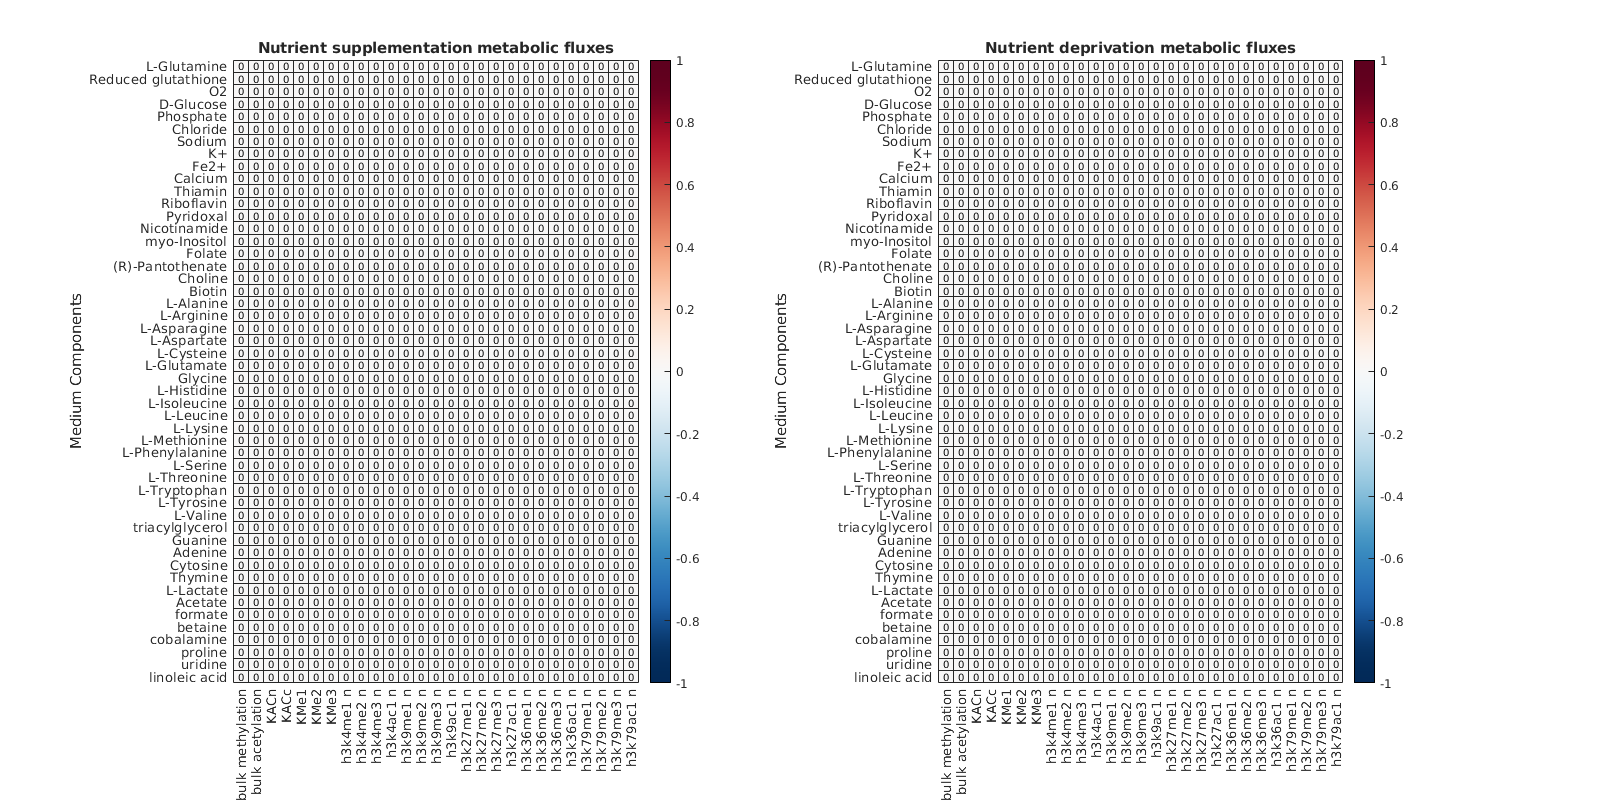

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation_flux{1}, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation_flux{1}, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
set(gcf,'position',[0, 0, 1600, 800]);